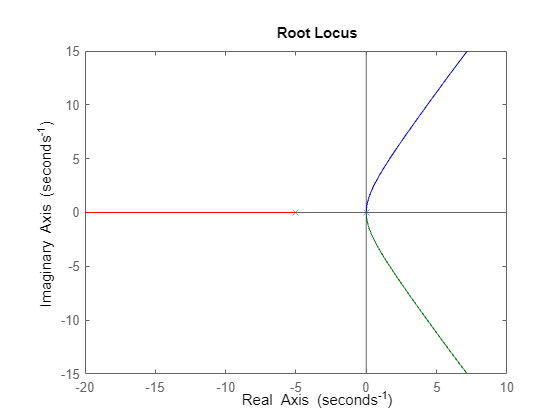

K =
 
      10 s + 8
  -----------------
  s^3 + 9 s^2 + 8 s
 
Continuous-time transfer function.
Model Properties


H =
 
          10 s^4 + 98 s^3 + 152 s^2 + 64 s
  -------------------------------------------------
  s^6 + 18 s^5 + 107 s^4 + 242 s^3 + 216 s^2 + 64 s
 
Continuous-time transfer function.
Model Properties


                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -6.28e-01     1.00e+00       6.28e-01         1.59e+00    
 -1.00e+00     1.00e+00       1.00e+00         1.00e+00    
 -2.00e+00     1.00e+00       2.00e+00         5.00e-01    
 -6.37e+00     1.00e+00       6.37e+00         1.57e-01    
 -8.00e+00     1.00e+00       8.00e+00         1.25e-01    


% Transfer function for 1/(s(s^2+4s+5))

num = [1];
den = [1, 5, 0, 0];

% Create transfer function
sys = tf(num, den);

% Plot root locus
rlocus(sys);

G = tf([1], [1 ])

K = tf([10,8],[1,9,8,0])
H = K/(1+K)
damp(H)

clear


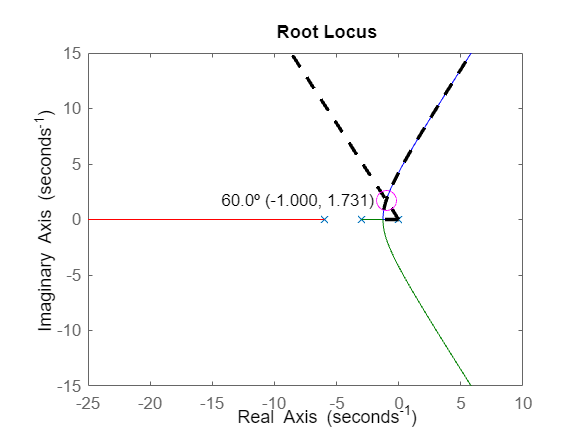

addpath("C:\Users\QiLin\Downloads\intersections")
clf
s=tf('s');
GH = tf(10,[1 9 18 0]);
rlocus(GH)

% Get handle to blue line 
ax = gca(); 
curveLine = findobj(ax, 'Type','Line','Color', 'b', 'Marker','none');
% Find intersection of the angle from x-axis at 
% origin (0,0)
ang = 60; % deg from negative x-axis into quadrant 3
xLine = [0, ax.XLim(1)]; 
yLine = [0, tand(-ang)*xLine(2)];
[x0,y0,~,~] = intersections(curveLine.XData, curveLine.YData, xLine, yLine);
% Plot the lines and intersection
hold(ax,'on')
plot(ax, curveLine.XData, curveLine.YData, 'k--', 'LineWidth', 2)
plot(ax, xLine, yLine, 'k--', 'LineWidth', 2)
% remove (0,0) intersection and label intersection
isNot0 = x0~=0 & y0~=0; 
plot(ax, x0(isNot0), y0(isNot0), 'mo','MarkerSize', 12)
text(ax, x0(isNot0)*2, y0(isNot0), ...
    sprintf('%.1f%s (%.3f, %.3f)',ang,char(186),x0(isNot0), y0(isNot0)), ...
    'HorizontalAlignment', 'right')
saveas(gcf, fullfile("A3_imgs/intersect.png"));

% Define the transfer function
num = 1.4;
den = [1 5 5 0];
sys = tf(num, den);
H=sys/(1+sys)

H =
 
               1.4 s^3 + 7 s^2 + 7 s
  -----------------------------------------------
  s^6 + 10 s^5 + 35 s^4 + 51.4 s^3 + 32 s^2 + 7 s
 
Continuous-time transfer function.
Model Properties


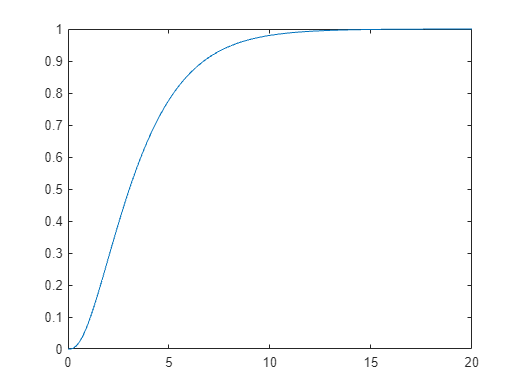

% Set the time range and step size
t = 0:0.01:20;

% Simulate the system response to a unit step input
y = step(H, t);

% Plot the response
plot(t, y)

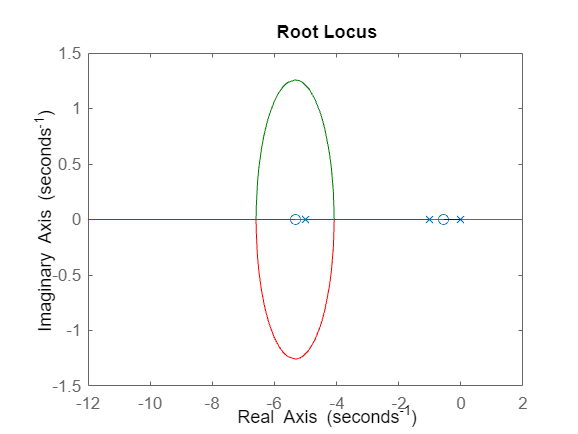

num = [0.17 1 0.5];
den = [1 6 5 0];
G = tf(num, den);

figure;
rlocus(G)

filename = 'A3_imgs/A3_q6_locus.png';
saveas(gcf, fullfile(filename));

%%% Define the transfer function
% kp(1+a/s) = kp s + a*kp / s
kp=45.049;
alpha=0.5;
beta=0.17;

C = tf([kp*beta kp kp*alpha],[1 0]);
G = tf(1, [1 6 5]);
sys = G*C/(1+G*C);

%%% Get Step Input Result
step_sys = feedback(sys, 1);
step_info = stepinfo(step_sys);

% Simulate the response to a step input
t = 0:0.01:20;
y = step(sys, t);

% Calculate the steady-state error
steady_state_value_step = y(end);
input_mag_step = 1;

%%% Get Ramp Input Result
% Simulate the response to the ramp input
t = 0:0.1:10;
ramp_input = t;
[y, t] = lsim(sys, ramp_input, t);

% Calculate the steady-state error
steady_state_value = y(end);
input_mag = max(ramp_input);

disp("DS1: Step SS Error="+abs(steady_state_value_step - input_mag_step)/1)

DS1: Step SS Error=1.7317e-06


disp("DS2: Ramp SS Error="+abs(steady_state_value - input_mag)/1)

DS2: Ramp SS Error=0.22137


disp("DS3: Overshoot="+step_info.Overshoot)

DS3: Overshoot=0


disp("DS4: Settling time="+step_info.SettlingTime)

DS4: Settling time=0.40168


% Define the criteria
DS1_target = 0.01;
DS2_target = 0.28;
DS3_target = 5;
DS4_target = 1.5;

% Define the parameter ranges
kp_range = 10:1:30;
alpha_range = 0.5:0.05:1.3;
beta_range = 0.05:0.01:0.2;

% Initialize the minimum kp and the minimum DS4
min_kp = Inf;
min_alpha = Inf;
min_Beta = Inf;
% Loop over all possible combinations of kp, alpha, and beta
for kp = kp_range
    for alpha = alpha_range
        for beta = beta_range
            % Calculate the DS1, DS2, DS3, and DS4
            [DS1, DS2, DS3, DS4] = calculate_DS(kp, alpha, beta);
            
            % Check if the criteria are satisfied and update the minimum
            if DS1 < DS1_target && DS2 < DS2_target && DS3 < DS3_target && DS4 < DS4_target
                    if min([kp kp*alpha kp*beta]) < min([min_kp min_kp*min_alpha min_kp*min_beta])
                        min_kp = kp;
                        min_alpha = alpha;
                        min_beta = beta;
                    end
            end
        end
    end
end

% Print the minimum kp and minimum DS4
if min_kp == Inf
    disp("No combination of parameters satisfies the criteria.")
else
    disp("Minimum kp: " + min_kp)
    disp("Minimum alpha: " + min_alpha)
    disp("Minimum beta: "+ min_beta)
end

Minimum kp: 19


Minimum alpha: 0.95


Minimum beta: 0.1



[DS1, DS2, DS3, DS4] = calculate_DS(min_kp, min_alpha, min_beta)

DS1 = 1.1769e-11

DS2 = 0.2770

DS3 = 4.7056

DS4 = 0.9436

% QUESTION FIVE
K = 1.4

K = 1.4000

Kt = 5

Kt = 5


G1 = tf([1],[1 5 0 0])

G1 =
 
       1
  -----------
  s^3 + 5 s^2
 
Continuous-time transfer function.
Model Properties


G2 = tf([Kt 0],[1])

G2 =
 
  5 s
 
Continuous-time transfer function.
Model Properties



G = G1/(1+G1*G2);
GG = (K*G)/(1+K*G)

GG =
 
                  1.4 s^9 + 21 s^8 + 112 s^7 + 245 s^6 + 175 s^5
  -------------------------------------------------------------------------------
  s^12 + 20 s^11 + 160 s^10 + 651.4 s^9 + 1421 s^8 + 1612 s^7 + 870 s^6 + 175 s^5
 
Continuous-time transfer function.
Model Properties



t = 0:0.01:20;

% Step Info
step_info = stepinfo(GG)

step_info = struct with fields:
         RiseTime: 5.6126
    TransientTime: 9.9918
     SettlingTime: 9.9918
      SettlingMin: 0.9008
      SettlingMax: 0.9992
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9992
         PeakTime: 16.1918



% Simulate the system response to a unit step input
y = step(GG, t);

% Plot the response
plot(t, y)
title_plot = ['Rise Time: ' num2str(step_info.RiseTime) ', Settling Time: ' num2str(step_info.SettlingTime) ', Overshoot: ' num2str(step_info.Overshoot)]

title_plot = 'Rise Time: 5.6126, Settling Time: 9.9918, Overshoot: 0'

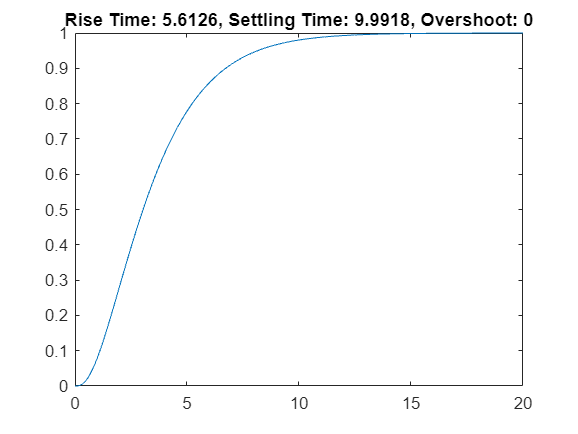

title(title_plot)

filename = 'A3_imgs/A3_q5_step.png';
saveas(gcf, fullfile(filename));

G = tf([1],[1 5 5 0])

G =
 
          1
  -----------------
  s^3 + 5 s^2 + 5 s
 
Continuous-time transfer function.
Model Properties


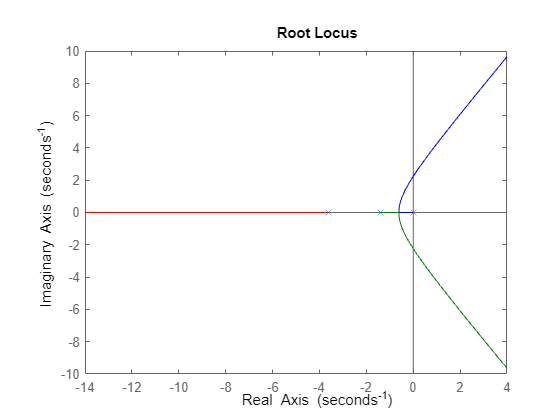

figure;
rlocus(G)


saveas(gcf, fullfile("A3_imgs/q5_e.png"));

Error using saveas
Invalid or missing path: A3_imgs\q5_e.png

G =
 
          1
  -----------------
  s^3 + 5 s^2 + 5 s
 
Continuous-time transfer function.
Model Properties


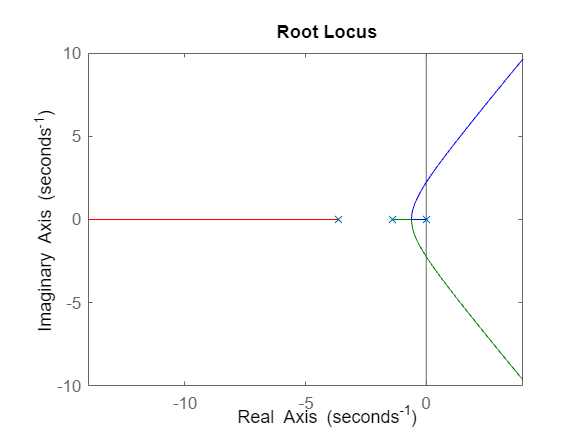

%%%%%%%%%%%%%%%%% TRY AGAIN %%%%%%%%%%%%%%%%%%%%%%%


%%% Define the transfer function
% kp(1+a/s) = kp s + a*kp / s
kp= 12;
alpha=0.7;
beta=0.12;

C = tf([kp*beta kp kp*alpha],[1 0])

C =
 
  1.44 s^2 + 12 s + 8.4
  ---------------------
            s
 
Continuous-time transfer function.
Model Properties


G = tf(1, [1 6 5])

G =
 
        1
  -------------
  s^2 + 6 s + 5
 
Continuous-time transfer function.
Model Properties


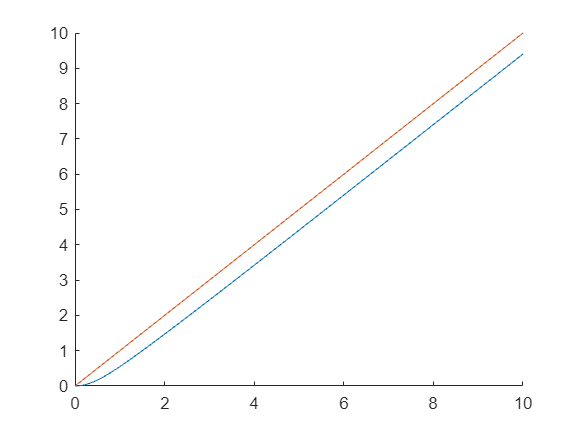

sys = G*C/(1+G*C);

%%% Get Ramp Input Result
% Simulate the response to the ramp input
t = 0:0.1:10;
ramp_input = t;
[y, t] = lsim(sys, ramp_input, t);

figure;
hold on;
plot(t, y)
plot(t, t)
hold off;


y(end)

ans = 9.4051

ramp_input(end)

ans = 10


% Calculate the steady-state error
steady_state_value = y(end);
input_mag = max(ramp_input);

disp("DS1: Step SS Error="+abs(steady_state_value_step - input_mag_step)/1)

DS1: Step SS Error=1.7317e-06


disp("DS2: Ramp SS Error="+abs(steady_state_value - input_mag)/1)

DS2: Ramp SS Error=0.59495


disp("DS3: Overshoot="+step_info.Overshoot)

DS3: Overshoot=0


disp("DS4: Settling time="+step_info.SettlingTime)

DS4: Settling time=0.40168


ans =     2.8000    6.1523


function [DS1, DS2, DS3, DS4] = calculate_DS(kp, alpha, beta)
    % Define the transfer function
    C = tf([kp*beta kp kp*alpha],[1 0]);
    G = tf(1, [1 6 5]);
    sys = G*C/(1+G*C);

    % Get Step Input Result
    step_sys = feedback(sys, 1);
    step_info = stepinfo(step_sys);
    t = 0:0.01:20;
    y = step(sys, t);

    % Calculate the steady-state error for step input
    steady_state_value_step = y(end);
    input_mag_step = 1;

    % Get Ramp Input Result
    t = 0:0.1:10;
    ramp_input = t;
    [y, t] = lsim(sys, ramp_input, t);

    % Calculate the steady-state error for ramp input
    steady_state_value = y(end);
    input_mag = max(ramp_input);

    % Return DS1, DS2, DS3, and DS4 as outputs
    DS1 = abs(steady_state_value_step - input_mag_step)/1;
    DS2 = abs(steady_state_value - input_mag)/1;
    DS3 = step_info.Overshoot;
    DS4 = step_info.SettlingTime;
end